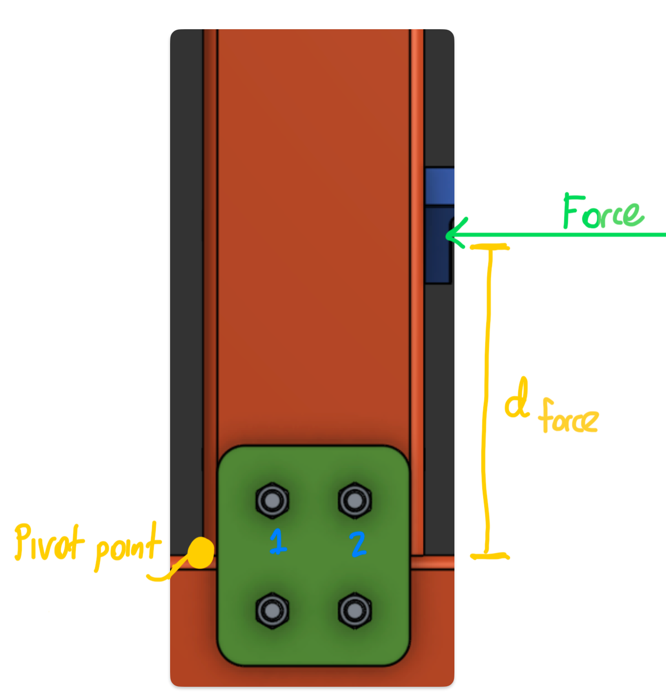

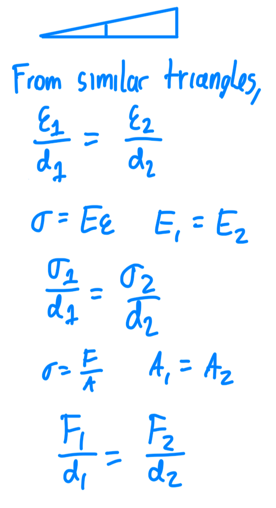

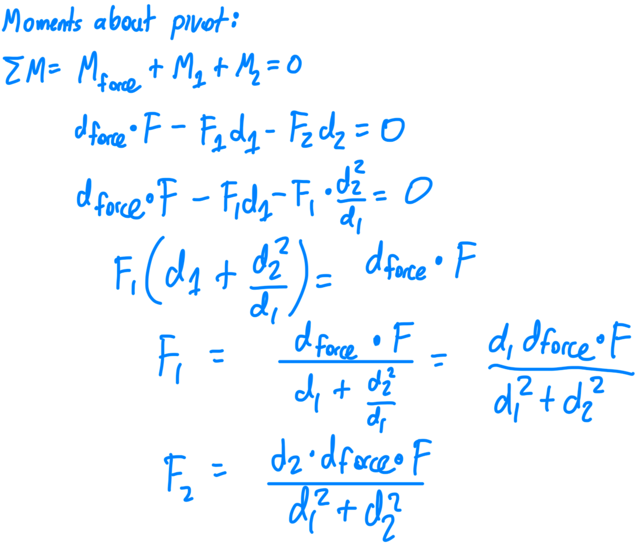

force    = 1000/1000; % kips
d_force  = 6; % in
d1       = 1; % in
d2       = 2.5; % in

t_gusset = 0.25; % in
t_spar   = 0.25; % in

hole_dia = 0.375; % in

bolt_shear_strength   = 44; % ksi
spar_bearing_strength = 33; % ksi

f1 = d1*d_force*force/(d1^2+d2^2); % kips
f2 = d2*d_force*force/(d1^2+d2^2); % kips

% Two shear planes --------------------------v
bearing_stress_1 = f1/(hole_dia*t_spar)    / 2; % ksi
shear_stress_1   = f1/(.25*pi*hole_dia^2)  / 2; % ksi

bearing_stress_2 = f2/(hole_dia*t_spar)    / 2; % ksi
shear_stress_2   = f2/(.25*pi*hole_dia^2)  / 2; % ksi

showFOS("Hole 1 Bearing", spar_bearing_strength, bearing_stress_1);

Hole 1 Bearing            	Stress: 4.4 MPa 	FOS: 7.48

showFOS("Bolt 1 Shear", bolt_shear_strength, shear_stress_1);

Bolt 1 Shear              	Stress: 3.7 MPa 	FOS: 11.74


showFOS("Hole 2 Bearing", spar_bearing_strength, bearing_stress_2);

Hole 2 Bearing            	Stress: 11.0 MPa 	FOS: 2.99

showFOS("Bolt 2 Shear", bolt_shear_strength, shear_stress_2);

Bolt 2 Shear              	Stress: 9.4 MPa 	FOS: 4.70